clear;
clc;

% LoRa Parameters
spreadFactor = 10;   % Spreading Factor
bandwidth = 125e3;   % Bandwidth (Hz)
carrierFrequency = 915e6; % Carrier Frequency (Hz)
transmitPower = 20;  % Transmission Power (dBm)


messageToSend = "Hi Tunnel Rover"; % Message to Transmit

## Sampling

% Sampling Parameters
samplingFrequency = 10e6;  % Sampling Frequency (Hz)
centerFrequency = 433e6;   % Center Frequency (Hz)

## Transmit Signal


% Transmit Signal Generation
loraSignal = LoRa_Tx(messageToSend, bandwidth, spreadFactor, transmitPower, samplingFrequency, centerFrequency - carrierFrequency);
signalPower = 10 * log10(rms(loraSignal).^2);
disp(['Transmit Power: ', num2str(signalPower), ' dBm']);

Transmit Power   = 20 dBm


## **Transmission Delay (ToA Calculation)**

% Time-on-Air (ToA) Calculation
payloadBytes = length(messageToSend); % Payload size in bytes
crcSize = 2;    % CRC size in bytes
headerSize = 13; % Header size in bytes
codingRate = 4/5; % Coding rate

toa = (2^spreadFactor / bandwidth) * (8 + max((payloadBytes + crcSize + headerSize) / codingRate, 0)) / spreadFactor;
disp(['Transmission Delay (Time-on-Air): ', num2str(toa), ' seconds']);


Transmission Delay (Time-on-Air) = 0.022938 seconds


## Plots

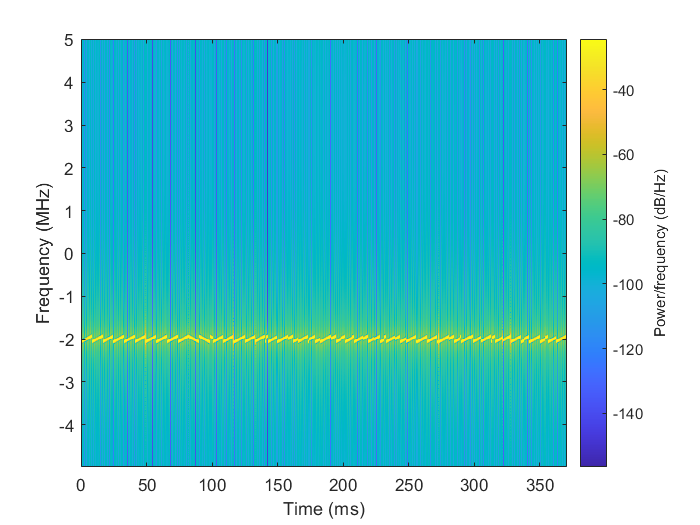

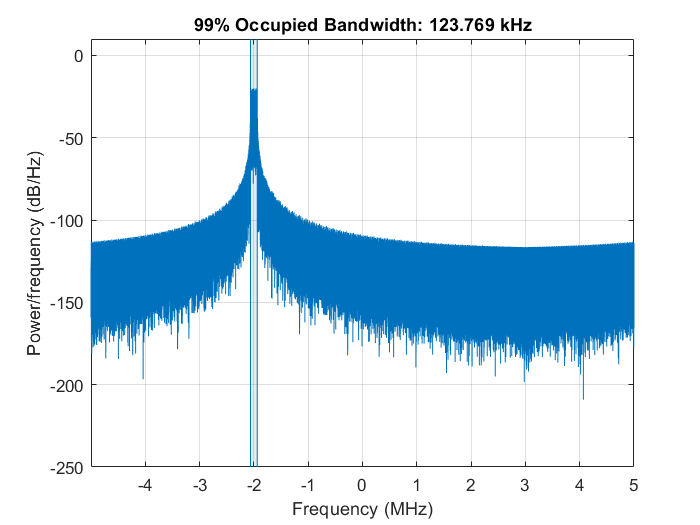

% Signal Plots
figure;
spectrogram(loraSignal, 500, 0, 500, samplingFrequency, 'yaxis', 'centered');
title('Spectrogram of Transmitted Signal');


figure;
obw(loraSignal, samplingFrequency);
title('Occupied Bandwidth of Transmitted Signal');

## Received Signal

message_out = LoRa_Rx(signalIQ,BW,SF,2,Fs,Fc - fc) ;

## Message Out

disp(['Message Received = ' char(message_out)])

Message Received = Hi Tunnel Rover


## Add Noise

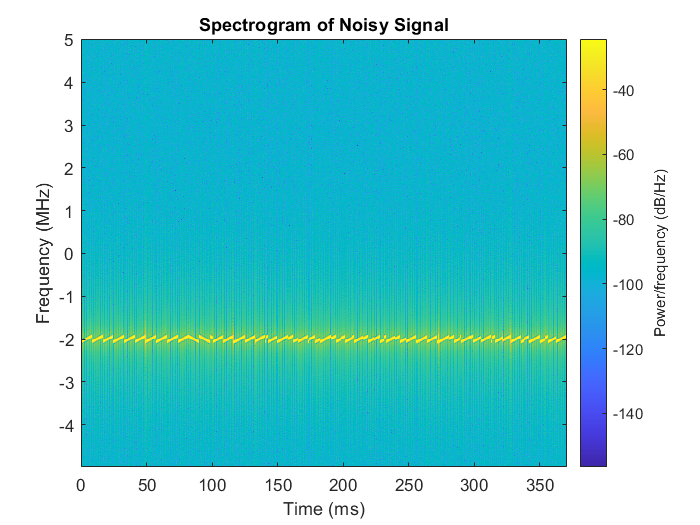

% Add Noise to the Signal
signalToNoiseRatio = 50; % SNR in dB
noisySignal = awgn(loraSignal, signalToNoiseRatio, 'measured');

%% Plots
figure(1)
spectrogram(noisySignalIQ, 500, 0, 500, Fs, 'yaxis', 'centered')
title('Spectrogram of Noisy Signal');

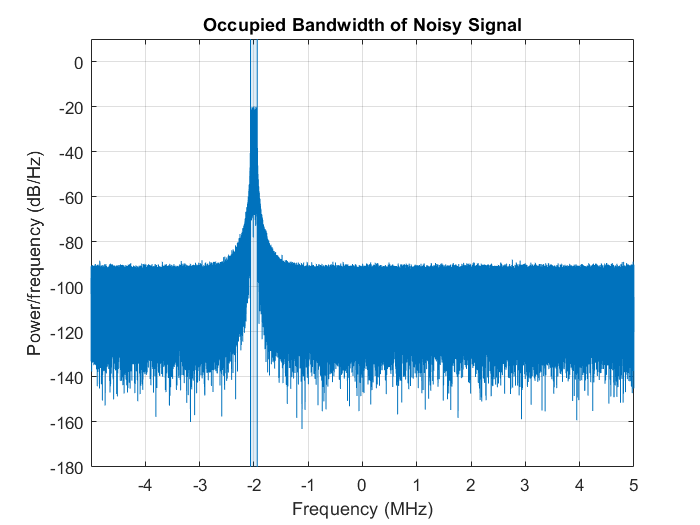


figure(2)
obw(noisySignalIQ, Fs);
title('Occupied Bandwidth of Noisy Signal');


%% Received Signal
message_out = LoRa_Rx(noisySignalIQ, BW, SF, 2, Fs, Fc - fc);

%% Message Out
disp(['Message Received = ' char(message_out)])

Message Received = Hi Tunnel Rover
